# Imaging with AIRI

## Description

AI for Regularization in Imaging, dubbed AIRI`,` is a Plug-and-Play (PnP) algorithm solving inverse imaging problems [1]. By inserting carefully trained AIRI denoisers into the proximal splitting algorithms, one waives the computational complexity of optimisation algorithms induced by sophisticated image priors, and the sub-optimality of handcrafted priors compared to Deep Neural Networks. AIRI is underpinned by the forward-backward iterative scheme. The details of the algorithm are discussed in the following papers.

- [1] Terris, M., Tang, C., Jackson, A., & Wiaux, Y., [Plug-and-play imaging with model uncertainty quantification in radio astronomy](https://arxiv.org/abs/2312.07137v2), 2023, *preprint arXiv:2312.07137.*

- [2] Terris, M., Dabbech, A., Tang, C., & Wiaux, Y., [Image reconstruction algorithms in radio interferometry: From handcrafted to learned regularization denoisers](https://doi.org/10.1093/mnras/stac2672). *MNRAS, 518*(1), 604-622, 2023.

- [3] Wilber, A. G., Dabbech, A., Jackson, A., & Wiaux, Y., [Scalable precision wide-field imaging in radio interferometry: I. uSARA validated on ASKAP data](https://doi.org/10.1093/mnras/stad1351). *MNRAS, 522*(4), 5558-5575, 2023.

In this tutorial, we focus on [a MATLAB implementation of AIRI](https://github.com/basp-group/AIRI) for small scale monochromatic intensity imaging in SII, from the environment setup, to imaging of simulated radio-interferometric data.

## Inverse Problem

The RI imaging inverse problem can be formulated as:

$\mathbf{\mathit{y}} = \mathbf{\Phi} \overline{\mathbf{\mathit{x}}} + \mathbf{\mathit{n}}$,

where $\mathbf\mathit{y}}$$\in \mathbb{C}^M$ is the measurement vector, $\overline{\mathbf{\mathit{x}}}$$\in \mathbb{R}^N$ is the unknown radio image, $\mathbf{\Phi}$$\in \mathbb{C}^{N \times M}$ is the measurement operator corresponding to incomplete Fourier sampling, and $\mathbf\mathit{n}}$$\in \mathbb{C}^M$ is the noise. Our task is reconstructing $\overline{\mathbf{\mathit{x}}}$ from the measurement $\mathbf\mathit{y}}$.

## AIRI's iteration structure

AIRI is underpinned by the forward-backward algorithmic structure from optimisation theory. The iteration structure takes a two step-update: a forward step enforcing data fidelity, followed by a backward denoising step.

$\mathbf{\mathit{x}}_{i+1} = \mathrm{D}_{\sigma} \left (  \mathbf{\mathit{x}}_{i} - \delta \mathbf{\Phi}^{\dagger}  \left ( \mathbf{\Phi} \mathbf{\mathit{x}}_{i} - \mathbf{\mathit{y}} \right ) \right)$,

where $\mathrm{D}$ represents the DNN denoiser parameterised by the noise level $\sigma$, and $\delta \in [0, 2/ \| \mathbf{\Phi} \|_{\mathrm{S}}^2]$ is a step size. $\| \cdot \|_{\mathrm{S}}$ stands for the the spectral norm. Here, we set the step size $\delta = 1.98 / \| \mathbf{\Phi} \|_{\mathrm{S}}^2$. 

The choice of the denoiser DNN, more specifically its noise level $\sigma$ is crucial for best results. In fact, when $\sigma$ is too large, the reconstructed image will be very smooth. In the opposite case, the reconstructed image will be grainy and noisy. In [1], we proposed to build a shelf of denoisers, each trained at a fixed noise level. In imaging, the denoiser DNN is selected from the shelf whose noise level is the closest to the inverse of the estimated target image dynamic range given by

$\sigma = \frac{\tau}{ \alpha \sqrt{2 \| \mathbf{\Phi} \|_{\mathrm{S}}^2 }}$,

where $\tau$ is the standard deviation of the data-domain noise $\mathbf{\mathit{n}}$ and $\alpha$ is the maximum intensity of the target image $\overline{\mathbf{\mathit{x}}}$. Meanwhile, a proper scaling factor will be applied to the denoiser's input to make sure it works at desired effective noise level. The value of $\alpha$ can be estimated from data. In other words, it can be estimated as the maximum intensity of the back-projected image normalised by the peak value of PSF $\mathrm{max} \left \{ \mathrm{Re} \left \{ \mathbf{\Phi}^{\dagger} \mathbf{\mathit{y}} \right \} / \kappa \right \}$, where $\kappa = \mathrm{max} \left \{ \mathrm{Re} \left \{ \mathbf{\Phi}^{\dagger} \mathbf{\Phi} \mathbf{\mathit{\delta}} \right \} \right \}$. Then in the reconstruction stage, we'll set $\alpha$ as $\mathrm{max} \{ \mathbf{\mathit{x}}_{i+1} \}$ and update the denoisers if necessary.

This heuristic has shown to be effective both in simulation and on real data. However, in some cases an adjustment of its value  - within one order of magnitude -  may be necessary for best results. The adjusting factor is by default set to 1 and can be fine-tuned if needed. Readers can refer to this [README](https://github.com/basp-group/AIRI/blob/main/config/README.md) for more details.

## Clone Repository

You can clone the repository to the current directory by running the command below.

!git clone --recurse-submodules https://github.com/basp-group/AIRI.git
cd ./AIRI

The `--recurse-submodules` flag is required so that the required sub-module [`RI-measurement-operator`](https://github.com/basp-group/RI-measurement-operator) will be cloned at the same time.

## Dependencies

To run this repository, your MATLAB version should be higher than R2019b. The scripts below will check whether the required toolboxes have been installed.

list_tb = matlab.addons.installedAddons().Name;
if ~ismember(list_tb, "Parallel Computing Toolbox")
    error("Please install Parallel Computing Toolbox!\n")
elseif ~ismember(list_tb, "Deep Learning Toolbox")
    error("Please install Deep Learning Toolbox!\n")
elseif ~ismember(list_tb, "Deep Learning Toolbox Converter for ONNX Model Format")
    error("Please install Deep Learning Toolbox Converter for ONNX Model Format\n")
else
    fprintf("All set!\n")
end

If you need to install missing toolboxes, you can go to the "HOME" tab of MATLAB. Then in "Add-Ons", click "Get Add-Ons" and search for the name of the toolbox in question.

## Pre-trained AIRI denoisers

We provided two shelves of denoisers trained with optical astronomical image dataset and MRI dataset respectively. The DNNs are in ONNX format readable in MATLAB, which can be downloaded with the coomands below.

websave("./airi_denoisers/v1_airi_astro-based_oaid_shelf.zip", "https://researchportal.hw.ac.uk/files/115109618/v1_airi_astro-based_oaid_shelf.zip");
websave("./airi_denoisers/v1_airi_mri-based_mrid_shelf.zip", "https://researchportal.hw.ac.uk/files/115109619/v1_airi_mri-based_mrid_shelf.zip");

Unzip both denoiser shelves by running: 

unzip("./airi_denoisers/v1_airi_astro-based_oaid_shelf.zip", "./airi_denoisers")
unzip("./airi_denoisers/v1_airi_mri-based_mrid_shelf.zip", "./airi_denoisers")
delete ./airi_denoisers/v1_airi_astro-based_oaid_shelf.zip ./airi_denoisers/v1_airi_mri-based_mrid_shelf.zip

## Test Dataset

In this tutorial, we provide a test dataset composed of a ground truth image in **.fits** format and associated measurement file in **.mat** format. The ground truth is an image of the radio galaxy 3c353. First, let us visualise the ground truth image.

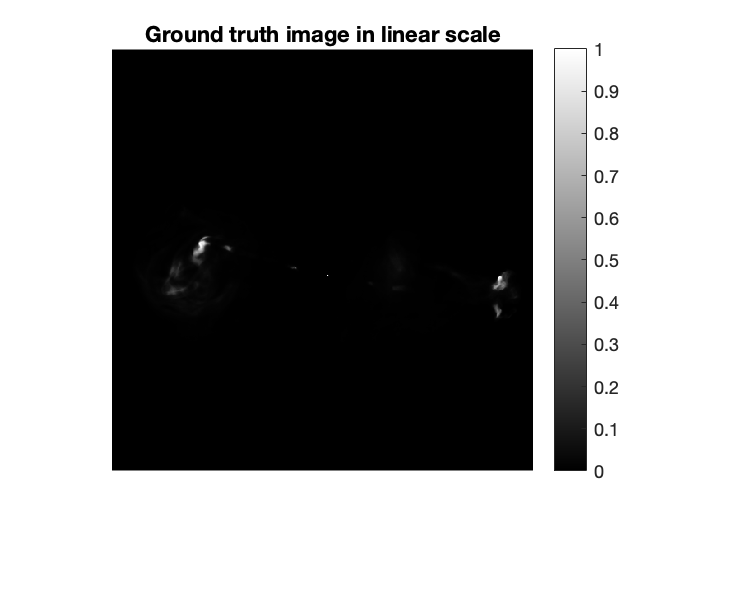

img_gdth = fitsread(fullfile("data","3c353_gdth.fits"));
figure
imshow(img_gdth)
colorbar
title("Ground truth image in linear scale")

Given the large dynamic range of the ground truth, only bright features are visible in linear scale. For a better visualisation, we map the pixels intensities in image $\mathbf{\mathit{x}}$ to the logarithmic scale using the equation below:


$$\textrm{rlog}(\mathit{\mathbf{x}})={\mathit{\mathbf{x}}}_{\max } \log_a (\frac{a}{{\mathit{\mathbf{x}}}_{\max } }\mathit{\mathbf{x}}+1)\;,$$


where $a$ corresponds to the dynamic range of the ground truth $\mathbf{\mathit{x}}$ and ${\mathit{\mathbf{x}}}_{\max }$ is the maximum intensity. In this case, $a = 2.5 \times10^3$ and ${\mathit{\mathbf{x}}}_{\max } =1\ldotp 0$.

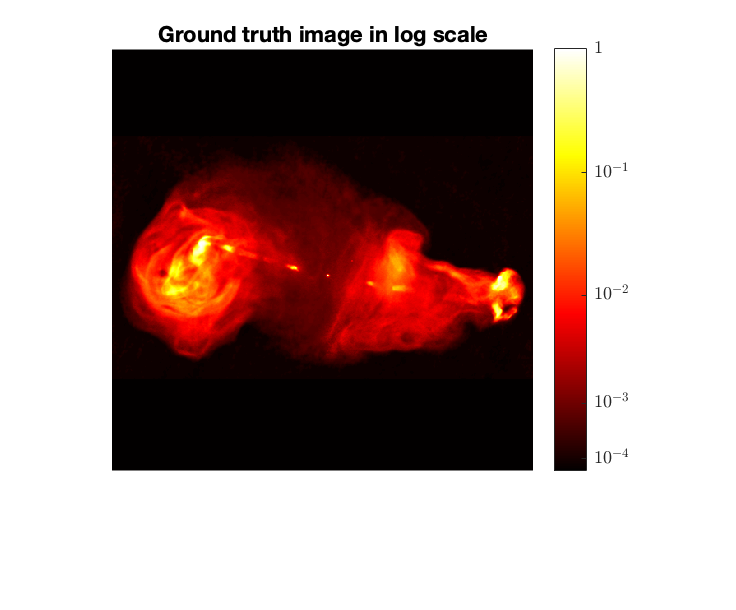

rlog = @(x, a) log10(a .* x + 1) ./ log10(a);
img_gdth_log = rlog(img_gdth, 2500);
figure
imshow(img_gdth_log, 'Colormap', colormap('hot'))
cb = colorbar;
ticks = rlog([1e-4, 1e-3, 1e-2, 1e-1, 1.0], 2500);
ticks(end) = 1;
cb.Ticks = ticks;
cb.TickLabels = {"$10^{-4}$", "$10^{-3}$", "$10^{-2}$", "$10^{-1}$", "$1$"};
cb.TickLabelInterpreter = 'latex';
title("Ground truth image in log scale")

The test measurement file  in `.mat `associated with the above ground truth can be loaded via the command below.

meas = load(fullfile("data/3c353_meas_dt_1_seed_0.mat"))

meas = struct with fields:
          frequency: 1.0000e+09
                  y: [201600×1 double]
                  u: [201600×1 double]
                  v: [201600×1 double]
                  w: [201600×1 double]
                 nW: [201600×1 double]
             nWimag: []
    maxProjBaseline: 2.5948e+04


The expected fields are listed below.

- "**y**" is a measurement/data  vector.

- "**u**" is a vector containing $u$ coordinates of the sampling position in units of the observation wavelength.

- "**v**" is a vector containing $v$ coordinates of the sampling position in units of the observation wavelength.

- "**w**" is a vector containing $w$ coordinates of the sampling position in units of the observation of wavelength.

- "**nW**" is a vector containing the so-called natural weights, corresponding to the inverse of the noise standard deviation. The vector constitutes a whitening operator to be applied to the data and injected in the measurement operator.

- "**nWimag**" is a vector containing the imaging weights if available, compensating for the non-uniform Fourier sampling and enhancing the effective resolution of the observations. The vector is **optional** and can be computed directly in the AIRI code.

- "**frequency**" is the observation frequency (in Hz).

- "**maxProjBaseline**" is the maximum projected baseline in  units of the observation wavelength, formally it equals to $\mathrm{max} \left \{ \sqrt{\mathbf{\mathit{u}}^2 + \mathbf{\mathit{v}}^2 } \right \}$.

In the context of narrow field RI imaging, the $w$ coordinates will not be considered in the measurement operator. The collection of the points $(\mathbf{\mathit{u}}, \mathbf{\mathit{v}})$ constitutes the Fourier sampling pattern also known as the $uv$-coverage. Meanwhile, we also provide example scripts for [generating synthetic measurement files](https://github.com/basp-group/RI-measurement-operator/blob/master/example_sim_ri_data.m) and [converting Measurement Sets (MS) to the **.mat **files](https://github.com/basp-group/AIRI/tree/main/ms2mat) with the same format.

## Image Reconstruction

The AIRI imager is launched using the function `run_imager`. This function has a mandatory input, which is the path of a configuration file, where all the parameters involved in the imaging process are defined. An example configuration file, `./config/airi_sim.json`, is provided. The readers can refer to this [README](https://github.com/basp-group/AIRI/blob/main/config/README.md) for details about the fields in this file. The function `run_imager` also accepts **optional** name-argument pairs to overwrite corresponding fields in the configuration file. 

Here, we'll use denoisers trained with optical astronomical image dataset to reconstruct the image from the example test dataset. The target image size is $512 \times 512$, which is the same as the size of ground truth image. The image pixel size (in the unit of arcsec) can also be specified through both configuration file and the input argument. Otherwise, it will be calculated from the value of the max projected baseline and the super resolution factor as

$imPixelSize = \frac{180}{\pi} \times \frac{3600}{superresolution \times 2 \times maxProjBaseline}$.

The super resolution factor in this case is `1.0`, which means that the Fourier sampling is done at the same spatial bandwidth as the ground truth image. For the data weighting scheme, we only consider natural weighting in this example.

The full imaging command is shown below. We recommend running it on machines with NVIDIA GPU and MATLAB will automatically utilis CUDA to accelerate the denoising operation. It will take around 20 minutes in total with CUDA acceleration.

run_imager("./config/airi_sim.json", ...                    path of the configuration file
    'srcName', "example", ...                               name of the target src used for output filenames
    'dataFile', "./data/3c353_meas_dt_1_seed_0.mat", ...    path of the measurement file
    'resultPath', "./results", ...                          path where the result folder will be created
    'algorithm', "airi", ...                                algorithm that will be used for imaging
    'imDimx', 512, ...                                      horizontal number of pixels in the final reconstructed image
    'imDimy', 512, ...                                      vertical number of pixels in the final reconstructed image
    'dnnShelfPath', "./airi_denoisers/shelf_oaid.csv", ...  path of the denoiser shelf configuration file
    'superresolution', 1.0, ...                             used if pixel size not provided
    'groundtruth', "./data/3c353_gdth.fits", ...            path of the groundtruth image when available, used to calculate SNR at the end
    'runID', 0 ...                                          identification number of the imaging run used for output filenames
  )

In the output log information, we can see that the heuristic noise level of the target image is approximately $3.7 \times 10^{-4}$ and the final selected denoiser is trained at noise level $3.2 \times 10^{-4}$. 

The dirty image of the example test set, which is defined as is defined as $\mathrm{Re} \left \{ \mathbf{\Phi}^{\dagger} \mathbf{\mathit{y}} \right \} / \kappa$, is shown below.

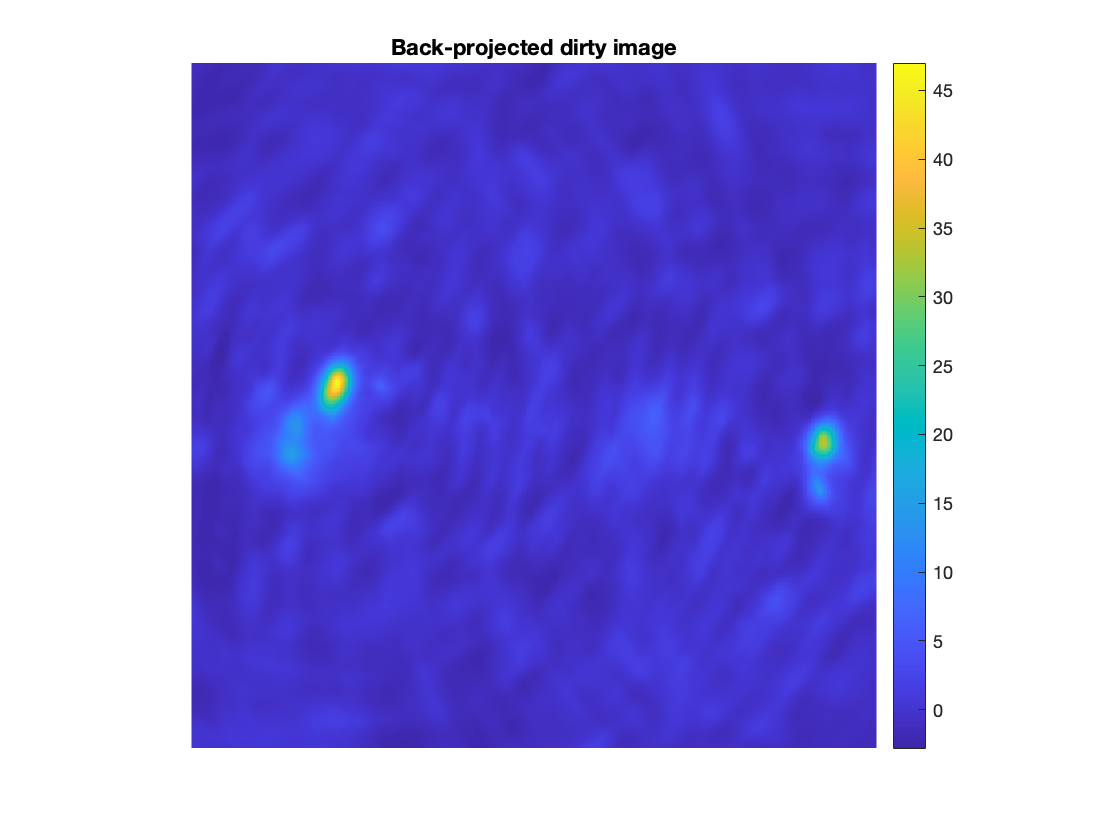

The script will yield reconstruction$\widetilde{\mathbf{\mathit{x}}}$shown below. The SNR is around `25.3 dB`. The SNR of the log scale image $\mathrm{rlog} ( \mathbf{\mathit{\widetilde{x}}} )$ is around `23.4 dB`.

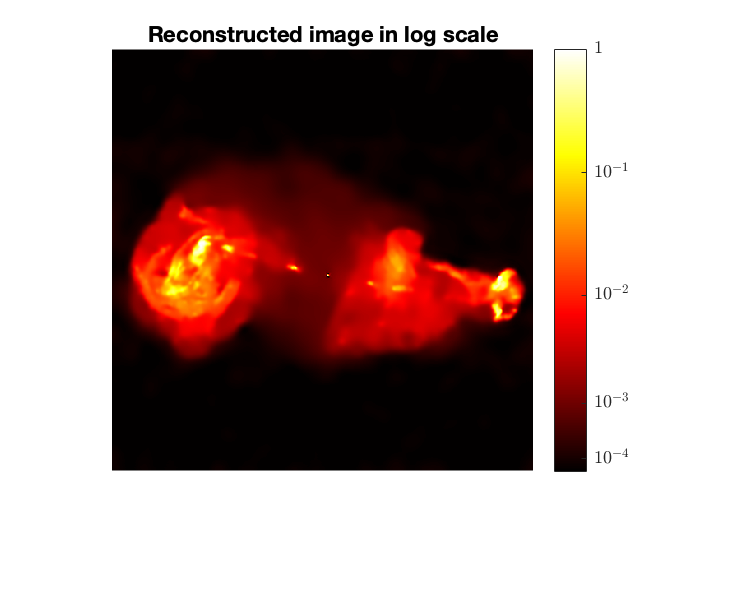

The residual dirty image is shown below and defined as $\left ( \mathrm{Re} \left \{ \mathbf{\Phi}^{\dagger} \mathbf{\mathit{y}} \right \} - \mathrm{Re} \left \{ \mathbf{\Phi}^{\dagger} \mathbf{\Phi} \widetilde{\mathbf{\mathit{x}}} \right \} \right ) 
/ \kappa$.

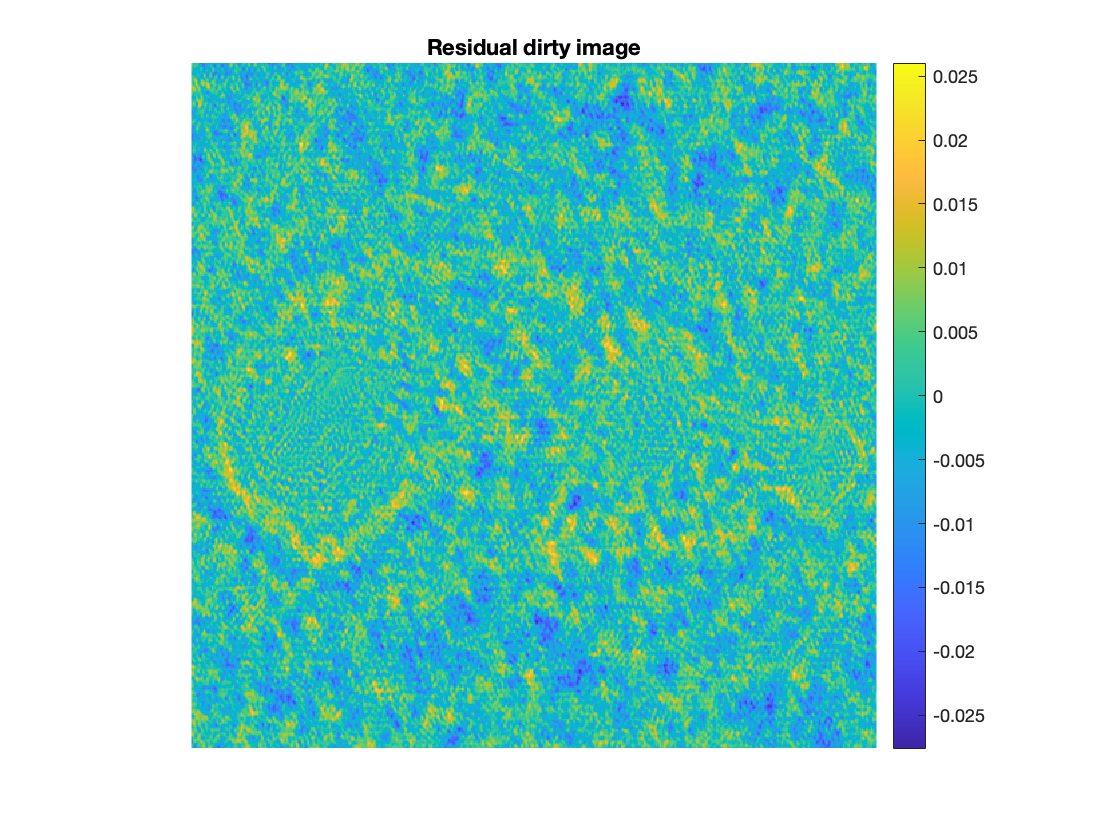

## Additional Functionalities

The code supports data-weighting schemes during imaging (uniform or Briggs weighting).  It provides the functionality to compute the imaging weights if not available in the input data file. This repository also provides implementations of other imaging algorithms, such as cAIRI, uPnP-BM3D and cPnP-BM3D. We kindly direct the readers to the full [README](https://github.com/basp-group/AIRI) of this repository for more information.